# Example 17.4

Consider the pulsed periodic waveform with fundamental period $T_0$ shown in [Fig. 76](https://cpjobling.github.io/eg-150-textbook/fourier_series/2/exp_fs1.html#fig-ex-17-4).

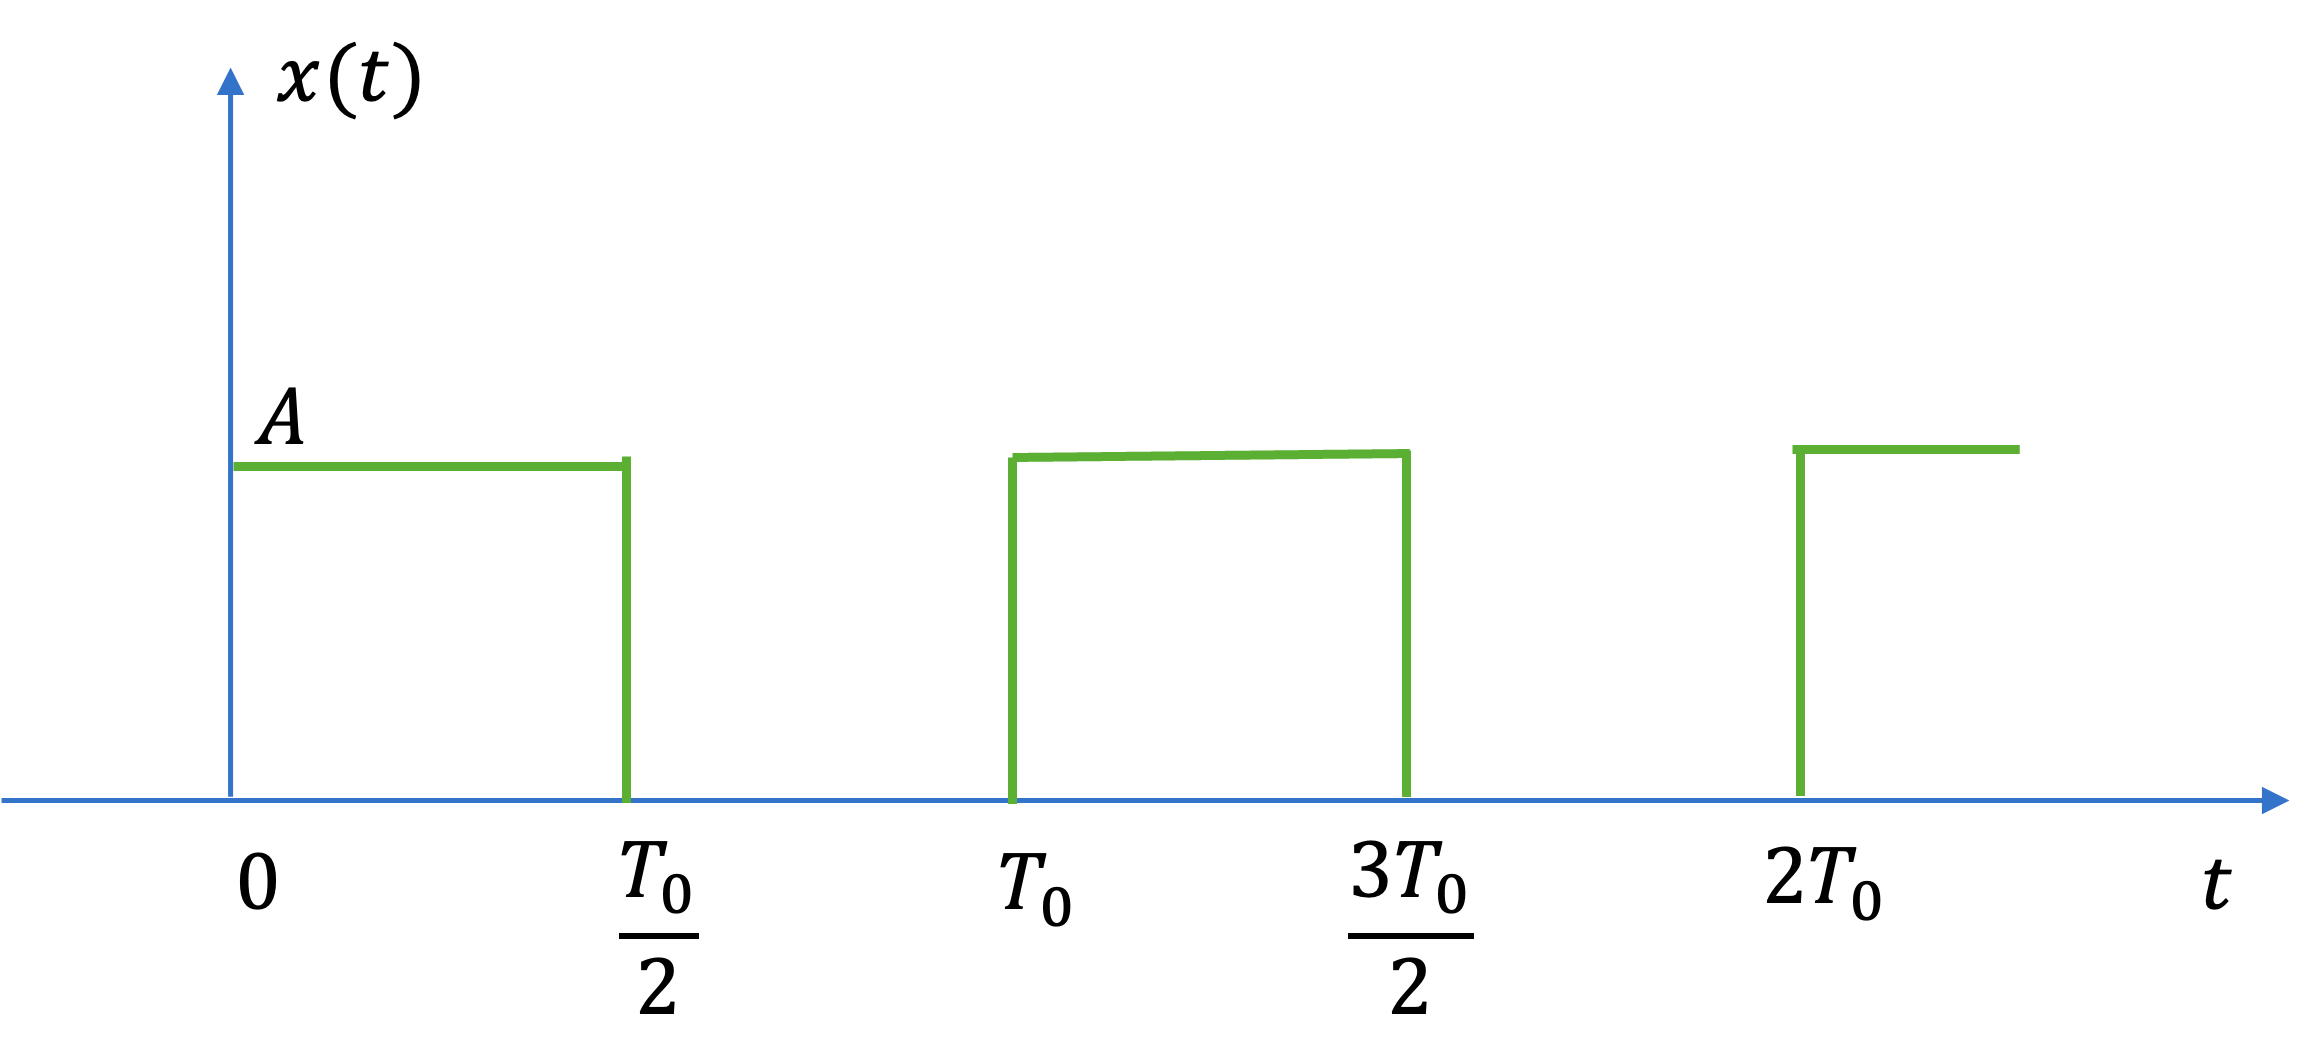

*Fig. 76 *Periodic Waveform for Example 17.4

a) Compute the Fourier series coefficients $C_k$ for this signal.

syms A theta k Omega_0 T_0 t
assume(k,'integer')
assume(A,'real')
assume(T_0>0)
C_0 = (A/T_0)*(int(1,t,0,T_0/2))

$$C\_0 = \frac{A}{2}$$

C_k = (A/T_0)*int(exp(-j*k*Omega_0*t),t,0,T_0/2)

$$C\_k = -\frac{A\,\left(\frac{\mathrm{i}}{\Omega_{0}\,k}-\frac{{\mathrm{e}}^{-\frac{\Omega_{0}\,T_{0}\,k\,\mathrm{i}}{2}}\,\mathrm{i}}{\Omega_{0}\,k}\right)}{T_{0}}$$


C_k = subs(C_k,Omega_0,sym(2*pi)/T_0)

$$C\_k = -\frac{A\,\left(\frac{T_{0}\,\mathrm{i}}{2\,k\,\pi }-\frac{T_{0}\,{\mathrm{e}}^{-\pi \,k\,\mathrm{i}}\,\mathrm{i}}{2\,k\,\pi }\right)}{T_{0}}$$

C_k = simplify(C_k)

$$C\_k = \frac{A\,\left({\left(-1\right)}^{k+\frac{1}{2}}-\mathrm{i}\right)}{2\,k\,\pi }$$

K = [1:11];
C_k = subs(C_k,k,K)

$$C\_k = \left(\begin{array}{ccccccccccc} -\frac{A\,\mathrm{i}}{\pi } & 0 & -\frac{A\,\mathrm{i}}{3\,\pi } & 0 & -\frac{A\,\mathrm{i}}{5\,\pi } & 0 & -\frac{A\,\mathrm{i}}{7\,\pi } & 0 & -\frac{A\,\mathrm{i}}{9\,\pi } & 0 & -\frac{A\,\mathrm{i}}{11\,\pi } \end{array}\right)$$


C_k_array = [C_minus_k,C_0,C_k]

$$C\_k\_array = \left(\begin{array}{ccccccccccccccccccccccc} \frac{A\,\mathrm{i}}{11\,\pi } & 0 & \frac{A\,\mathrm{i}}{9\,\pi } & 0 & \frac{A\,\mathrm{i}}{7\,\pi } & 0 & \frac{A\,\mathrm{i}}{5\,\pi } & 0 & \frac{A\,\mathrm{i}}{3\,\pi } & 0 & \frac{A\,\mathrm{i}}{\pi } & \frac{A}{2} & -\frac{A\,\mathrm{i}}{\pi } & 0 & -\frac{A\,\mathrm{i}}{3\,\pi } & 0 & -\frac{A\,\mathrm{i}}{5\,\pi } & 0 & -\frac{A\,\mathrm{i}}{7\,\pi } & 0 & -\frac{A\,\mathrm{i}}{9\,\pi } & 0 & -\frac{A\,\mathrm{i}}{11\,\pi } \end{array}\right)$$

Calculate and plot spectrum

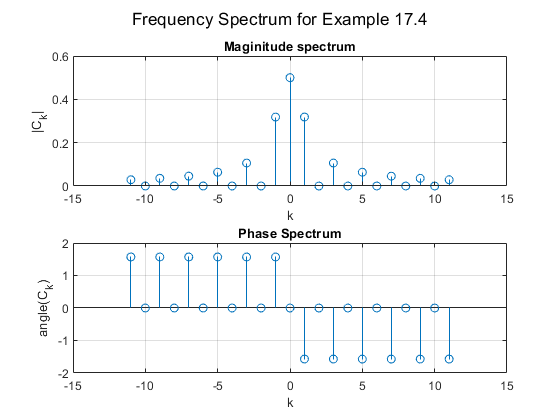

spectrum = subs(C_k_array,A,1);
mag = double(abs(spectrum));
phase = double(angle(spectrum));
subplot(211)
stem(-11:11,mag),...
    grid,title('Maginitude spectrum'),xlabel('k'),ylabel('|C_k|')
subplot(212)
stem(-11:11,phase),...
    grid,title('Phase Spectrum'),xlabel('k'),ylabel('angle(C_k)')
sgtitle('Frequency Spectrum for Example 17.4')

b) Give an expression for the trig. Fourier series for this signal.

a_k = C_k + conj(C_k)

$$a\_k = \left(\begin{array}{ccccccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

b_k = j*(C_k - conj(C_k))

$$b\_k = \left(\begin{array}{ccccccccccc} \frac{2\,A}{\pi } & 0 & \frac{2\,A}{3\,\pi } & 0 & \frac{2\,A}{5\,\pi } & 0 & \frac{2\,A}{7\,\pi } & 0 & \frac{2\,A}{9\,\pi } & 0 & \frac{2\,A}{11\,\pi } \end{array}\right)$$

a_0 = 2*C_0

$$a\_0 = A$$

ft = a_0/2;
for n = K
    ft = ft + a_k(n)*cos(n*Omega_0*t) + b_k(n)*sin(n*Omega_0*t);
end
ft

$$ft = \frac{A}{2}+\frac{2\,A\,\sin\left(\Omega_{0}\,t\right)}{\pi }+\frac{2\,A\,\sin\left(3\,\Omega_{0}\,t\right)}{3\,\pi }+\frac{2\,A\,\sin\left(5\,\Omega_{0}\,t\right)}{5\,\pi }+\frac{2\,A\,\sin\left(7\,\Omega_{0}\,t\right)}{7\,\pi }+\frac{2\,A\,\sin\left(9\,\Omega_{0}\,t\right)}{9\,\pi }+\frac{2\,A\,\sin\left(11\,\Omega_{0}\,t\right)}{11\,\pi }$$

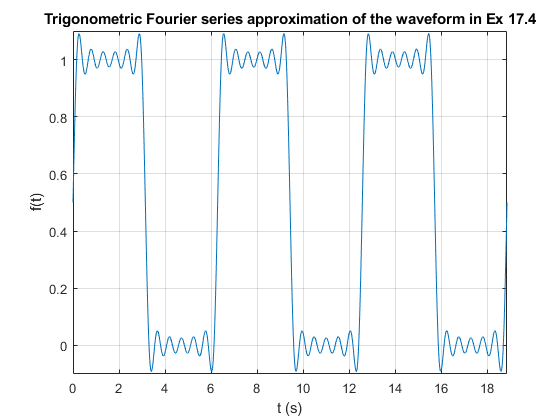

figure
figure
fplot(subs(ft,[A,Omega_0],[1,1]),[0,6*pi]),...
    grid,title('Trigonometric Fourier series approximation of the waveform in Ex 17.4'),...
    xlabel('t (s)'),ylabel('f(t)')